# 频域实验

## 一、系统辨识建模

读取实验室获得的频域数据

sheets=sheetnames("FrequentDomain.xlsx");
i=1;%选取俯仰通道数据进行建模
data=readmatrix("FrequentDomain.xlsx","Sheet",sheets(1));
freq=data(:,3*1-2);%原数据单位为Hz
A=data(:,3*1-1);%原数据单位为dB
P=data(:,3*1);

根据获得的频域数据，绘制频率特性曲线

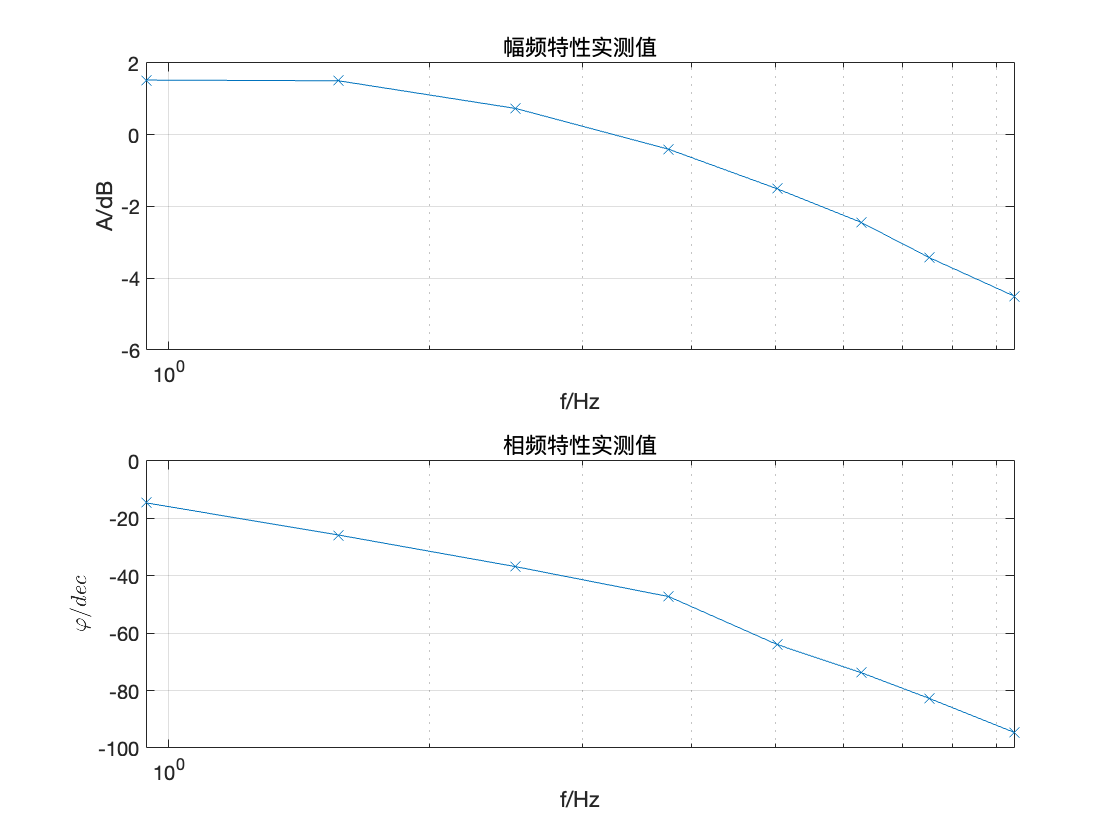

figure();
subplot(2,1,1);
semilogx(freq,A,'x-');
xlabel("f/Hz");
ylabel("A/dB");
title("幅频特性实测值")
grid on
subplot(2,1,2);
semilogx(freq,P,'x-');
title("相频特性实测值")
xlabel("f/Hz");
ylabel("$\varphi/dec$","Interpreter","latex")
grid on

np=[3 2];%俯仰通道可以将整个系统传递函数识别为3极点，0零点的形式
nz=[0 1];%偏航通道可以将整个系统传递函数识别为2极点，1零点的形式
A2=10.^(A./20);%将增益数据单位由dB转为1
h=A2.*exp(1i*P/180*pi);
data=idfrd(h,freq,0);
Pid=tfest(data,np(i),nz(i));
display(Pid)

Pid =
 
               2018
  -------------------------------
  s^3 + 21.6 s^2 + 448.3 s + 1634
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 0
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using TFEST on frequency response data "data".
Fit to estimation data: 93.58%                          
FPE: 0.002505, MSE: 0.0008348                           


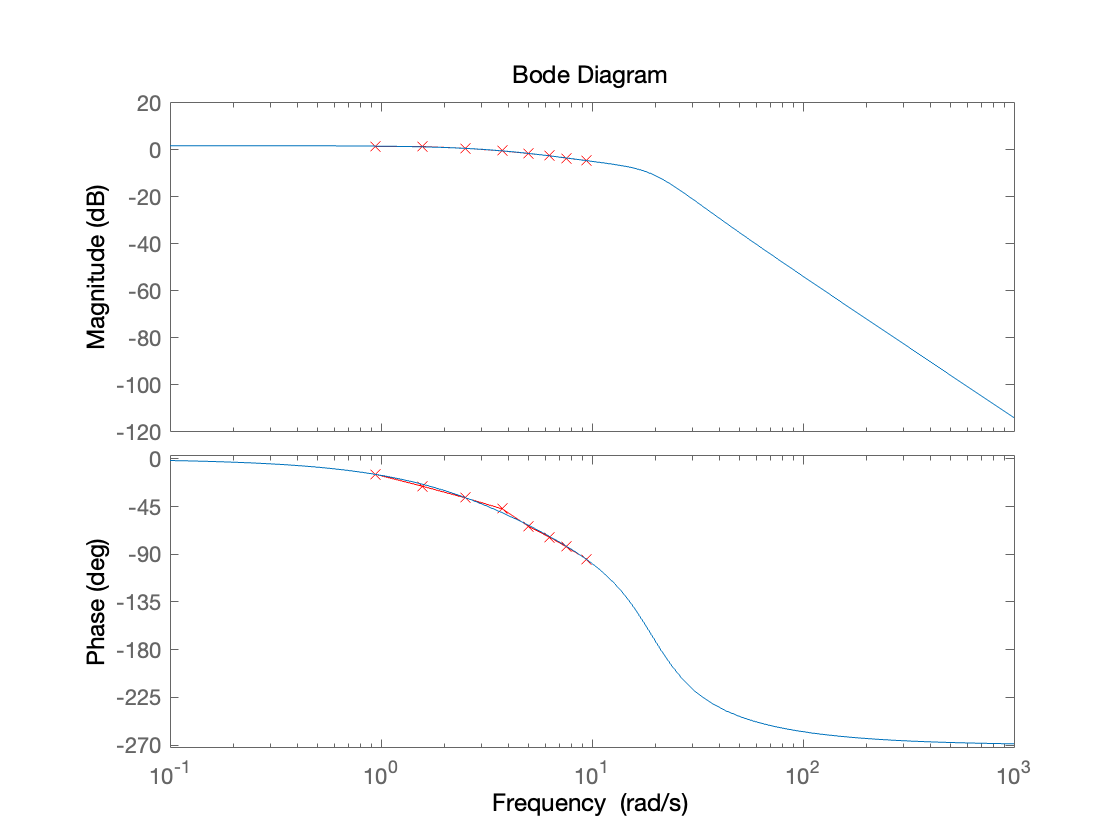

figure();
bode(data,'rx-',Pid);